clear all

%inicjalizacja zmiennych symulacji

%inicjalizacja obiektów
k = 1; % wzmocnienie obiektu
G_num = k;
G_denum = [720 1764 1624 735 175 21 1];

G_m_num = [1];
G_m_denum = [5 5 4 2];
tau_m = 0.1;

%inicjalizacja regulatorów
Kp_r_m = 1;
Ki_r_m = 1;
Kd_r_m = 0;

Kp_r_k = 0.5;
Ki_r_k = 0.2;

% zakłócenie
z = 0.5;

%inicjalizacja symulacji
sample_time = 0.01;
sys = tf(G_num, G_denum);
system_settling_time = stepinfo(sys).SettlingTime + 20;
stop_time = system_settling_time;

%inicjalizacja switchy
ident_switch = 1; % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m
correction_loop_switch = 2; % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna włączona
model_loop_switch = 2; % 1 - pętla z modelem włączona, 2 - pętla z modelem włączona
disturbance_switch = 2; % 1 - zakłócenie włączone, 2 - zakłócenie wyłączone

Impulsowa i skokowa funkcja przejścia:

%ustawienie switchy na skok jednostkowy

ident_switch = 1 % 1 - skok jednostkowy; 2 - sygnał z regulatora R_m

ident_switch = 1

correction_loop_switch = 2 % 1 - pętla korekcyjna włączona, 2 - pętla korekcyjna włączona

correction_loop_switch = 2

model_loop_switch = 2 % 1 - pętla z modelem włączona, 2 - pętla z modelem włączona

model_loop_switch = 2

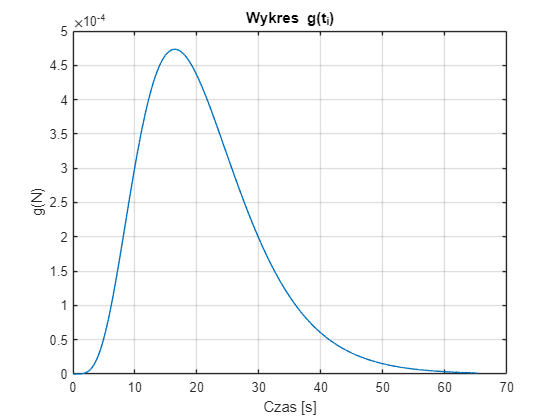

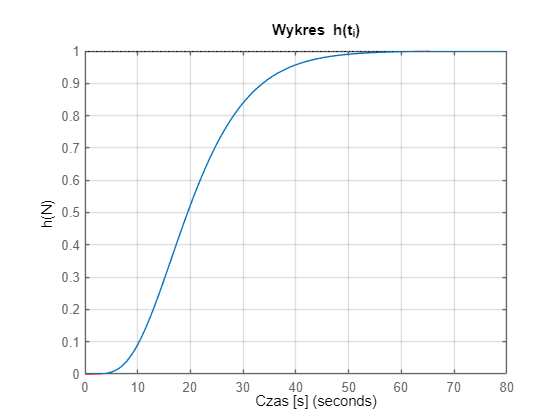



sim_out = sim("..\simulink_models\model_mfc.slx");
u = sim_out.u.Data;
y = sim_out.y.Data;
t = sim_out.tout;

[g, h] = impulse_step_transfer_function(u, y, t, sys);

Identyfikacja modelem Strejca: